# Electrode localization using FreeSurfer + iElectrodes

Written by Qian Chu

Max Planck - University of Toronto Centre

Contact: qian.chu@{mail.utoronto.ca, ae.mpg.de}

Version: 2400801

FreeSurfer version tested: 7.4.1

iElectrodes version tested: 1.020

## Checklist

Make sure that you have:

- Acquired the pre-op T1-weighted MRI scan (hereafter referred to as T1), the post-op CT scan (hereafter referred to as CT), and *optionally, the pre-op T2-weighted MRI scan (hereafter referred to as T2)*. The scans should be in DICOM (.dcm) or NIFTI (.nii) format.

- Make sure that .dcm files in one folder all belong to the same scan (i.e., create dedicated T1/T2/CT folders when preparing DICOM files)

- FreeSurfer installed on this computer. FreeSurfer can be installed on Linux or MacOS. Download instructions: [https://surfer.nmr.mgh.harvard.edu/fswiki/rel7downloads](https://surfer.nmr.mgh.harvard.edu/fswiki/rel7downloads)

- Downloaded iElectrodes from [https://sourceforge.net/projects/ielectrodes/files/latest/download](https://sourceforge.net/projects/ielectrodes/files/latest/download) and put the unzipped package in this elec_loc folder.

## Run sections below one by one

## Setup

clearvars, clc, close all

Specify paths:

- To FreeSurfer home directory ($FREESURFER_HOME)

cfg.dir_fs = '/home/qian/research/freesurfer';

- To FreeSurfer subject directory ($SUBJECTS_DIR)

cfg.dir_fs_subjects = '/home/qian/research/fs_subjects';

FREESURFER_HOME and SUBJECTS_DIR can be found in the command line outputs when you source FreeSurfer using *SetUpFreeSurfer.sh*

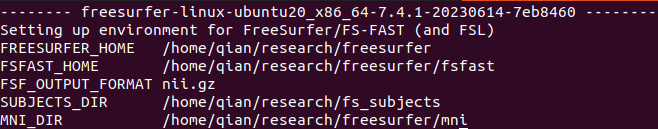

Type patient ID below:

pat.id  = "TWH223";

Set up paths:

elec_loc_path       = matlab.desktop.editor.getActiveFilename;
elec_loc_path_parts = split(elec_loc_path, filesep);
cfg.dir_el          = strjoin(elec_loc_path_parts(1:end-1), filesep);
addpath(fullfile(cfg.dir_el, 'functions'))
[cfg, pat] = el_init(cfg, pat);

## Import and preprocess scans

Say goodbye to manual preprocessing and coregistration of anatomical scans! The script here imports the T1, CT (and optionally T2) scans into a FreeSurfer subject folder. Moreover, it performs automatic scan centering, AC-PC alignment, coregistration, and defacing. The resulting scans are ready for electrode localization and data sharing.

### Procedure

- Run this section.

- ([UI prompt] [If preprocessed files already exist in the output folder] Indicate whether you want to re-import and re-preprocess the scans. If you choose no, the section will simply read and print the paths to preprocessed scans)

- [UI prompt] Indicate whether you have a T2 to include.

- [UI prompt] Indicate whether you want to import DICOM or NIFTI files.

- [UI file/directory selection] Select T1, CT (and T2) one by one according to prompt in the dialog title. For DICOM, you need to select a folder containing all .dcm files corresponding to one scan. For NIFTI, you need to select a single .nii file.

- Wait for processing. Before the T1 defacing stage, a message window will pop up with instructions on how to proceed.

- During CT processing, a viewer window will pop up to let you inspect the CT scan. You can adjust the minimum value to roughly determine an intensity threshold such that only bones and electrodes are visible to effectively de-identify the patient. Enter the value into the textbox.

- A viewer window will pop up at the end to allow you to inspect the scans overlaid on top of grayscale T1. The scans should be aligned to each other and defaced. Close the window when done inspecting.

### Output

- The elec_loc subfolder (`pat.dir.el`) in FreeSurfer subject folder with preprocessed (AC-PC aligned, defaced, and co-registered) scans. Scan file names comply with BIDS format (e.g., *sub-XXX_acq-preop_T1w.nii*). Compressed scans (.nii.gz) are further available in elec_loc/BIDS_outputs/anat.

- Updated `pat` structure.

TWH223 preprocessed scans not found. Importing...
Xiangrui Li's dicm2nii.m 20240606 (feedback to xiangrui.li@gmail.com)
Validating 160 files ... (160 valid)
Converting 1 series (Siemens) into 4-D .nii: subject 'TWH223'
 x2_25_201582031312445537927225969816249719291             320x320x160x1
Elapsed time by dicm2nii is 2.7 seconds

Validating 190 files ... (190 valid)
Converting 1 series (Canon) into 4-D .nii: subject 'TWH223'
 x2_25_139526643114442580216004409483586256561             512x512x190x1
Elapsed time by dicm2nii is 4.3 seconds

Validating 30 files ... (30 valid)
Converting 1 series (Siemens) into 4-D .nii: subject 'TWH223'
 x2_25_275189645682078415628511428356499860222             576x576x30x1
Elapsed time by dicm2nii is 1.0 seconds

**********PROCESSING T1**********

>>>>>Centering /home/qian/Desktop/Patient DICOMs/TWH223/t1/x2_25_201582031312445537927225969816249719291.nii
>>>>>Centered scan saved at /home/qian/research/fs_subjects/TWH223/elec_loc/temp_sub-TWH223_T1w_cent.n

ans = struct with fields:
      fname: '/home/qian/research/fs_subjects/TWH223/elec_loc/temp_sub-TWH223_CT_cent_coreg_deface_thres.nii'
        dim: [512 512 190]
         dt: [4 0]
      pinfo: [3×1 double]
        mat: [4×4 double]
          n: [1 1]
    descrip: 'spm - algebra'
    private: [1×1 nifti]



>>>>>Thresholded scan saved at /home/qian/research/fs_subjects/TWH223/elec_loc/temp_sub-TWH223_CT_cent_coreg_deface_thres.nii

**********PROCESSING T2**********

>>>>>Centering /home/qian/Desktop/Patient DICOMs/TWH223/t2/x2_25_275189645682078415628511428356499860222.nii
>>>>>Centered scan saved at /home/qian/research/fs_subjects/TWH223/elec_loc/temp_sub-TWH223_T2w_cent.nii

>>>>>Coregistering /home/qian/research/fs_subjects/TWH223/elec_loc/temp_sub-TWH223_T2w_cent.nii to /home/qian/research/fs_subjects/TWH223/elec_loc/temp_sub-TWH223_T1w_cent_acpc.nii

SPM12: spm_coreg (v7320)                           16:15:24 - 07/08/2024
Completed                               :          16:15:32 - 07/08/2024

>>>>>Coregistered scan saved at /home/qian/research/fs_subjects/TWH223/elec_loc/temp_sub-TWH223_T2w_cent_coreg.nii

>>>>>Masking /home/qian/research/fs_subjects/TWH223/elec_loc/temp_sub-TWH223_T2w_cent_coreg.nii accordin

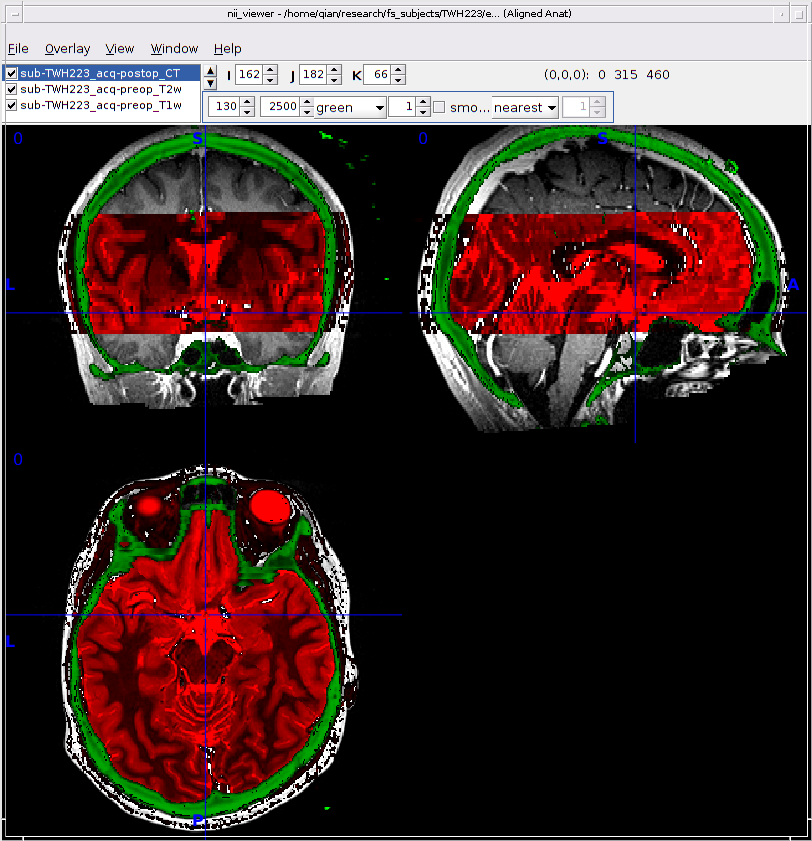

pat = el_import_scans(pat);

## Electrode labeling using iElectrodes

In this pipeline we use [iElectrodes](https://sourceforge.net/p/ielectrodes/wiki/Home/), an easy-to-use and robust toolbox for localizing intracranial electrodes. The code in this section launches iElectrodes.    

Welcome to iElectrodes.
iElectrodes toolbox is FOR RESEARCH PURPOSES ONLY. This software is
for research purposes only and has NOT BEEN APPROVED FOR CLINICAL USE.
Help about using iElectrodes can be found online in 
https://sourceforge.net/p/ielectrodes/wiki/Home/
You have the last version of iElectrodes :-)
Project estructure is beeing checked...
Checking done.


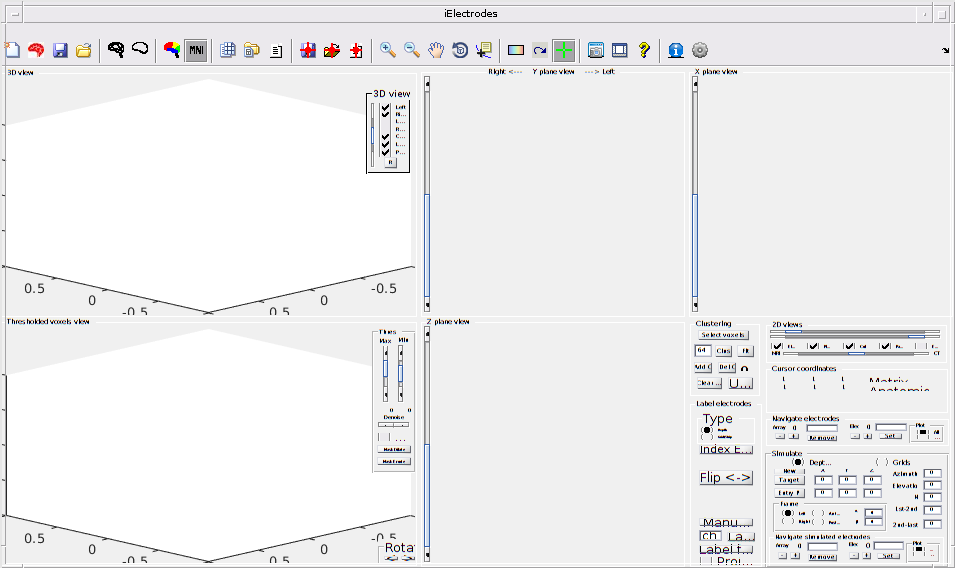

cd(pat.dir.el)
electrodes_gui

### iElectrodes toolbars

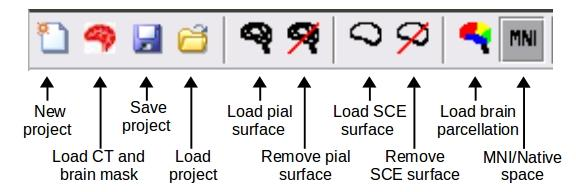

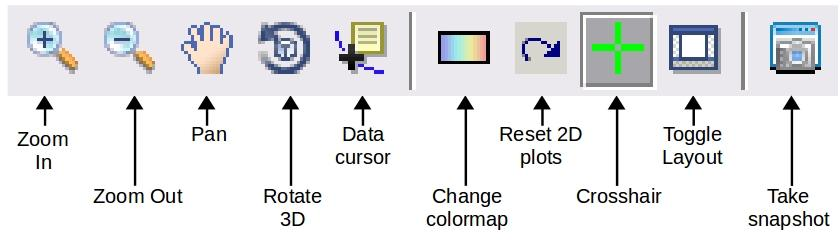

### Steps

- Click "New project" (see icon above) and load *sub-XXX_T1w.nii.* T1 scan will appear on the top right corner of the iElectrodes window once loading is complete

- Click "Load CT and brain mask" (see icon above). You will be prompted to select the CT scan *sub-XXX_CT.nii.*. After a while, you will be prompted again to select the brain mask. You can load the co-registered CT again. Using other masks like ribbon.nii might make it hard to visualize other landmarks like bolts, which are sometimes useful when navigating electrode locations.

- Follow [this tutorial](https://sourceforge.net/p/ielectrodes/wiki/Localization%20and%20labeling%20of%20intracranial%20electrodes/) to threshold CT, select above-threshold voxels, cluster and label electrodes.

- When you are done, save the project (see icon above) and name it as *sub-XXX.iel*. You can also save the project halfway and reload it using the "Load project" button.

## FreeSurfer recon-all with optional subfield segmentation

[https://surfer.nmr.mgh.harvard.edu/fswiki/recon-all](https://surfer.nmr.mgh.harvard.edu/fswiki/recon-all)

`recon-all` is a command line script in FreeSurfer. The name comes from "reconstruction of all structures," and this command calls a series of scripts for preprocessing, segmentation, and cortical surface reconstruction.

Freesurfer also has a hippocampus/amygdala subfield segmentation feature ([https://surfer.nmr.mgh.harvard.edu/fswiki/HippocampalSubfieldsAndNucleiOfAmygdala](https://surfer.nmr.mgh.harvard.edu/fswiki/HippocampalSubfieldsAndNucleiOfAmygdala)) with flexible scan input options (use T1 and/or T2).

### Inputs

- [Auto-loaded] Defaced, AC-PC aligned T1 (and T2)

- [Select from dropdown box] hippocampus and amygdala subfield segmentation option. It's recommended to select both T1 + T2 if you have both.

### Outputs

- FreeSurfer subject folder *$SUBJECTS_DIR/PATIENT_NAME*

After executing, wait a few minutes to make sure recon-all initiates without errors. The execution takes **10 hours or more **so it might be a good idea to run it overnight. Lay down .... ;)

subfield_seg_mode = 'T1+T2';
if contains(subfield_seg_mode, 'T2') && ~isfield(pat.t2, 'image')
    error('T2 was requested for subfield segmentation but no T2 was loaded in pat')
elseif ~exist(pat.t2.image, 'file')
    error('T2 was requested for subfield segmentation but scan not found')
end
el_fs_recon_all(cfg, pat)

mri_convert /home/qian/research/fs_subjects/TWH223/elec_loc/sub-TWH223_acq-preop_T1w.nii /home/qian/research/fs_subjects/TWH223/mri/orig/001.mgz 
reading from /home/qian/research/fs_subjects/TWH223/elec_loc/sub-TWH223_acq-preop_T1w.nii...
TR=2200.00, TE=0.00, TI=0.00, flip angle=0.00
i_ras = (-0.999502, -0.00957298, 0.0300564)
j_ras = (-0.0103861, 0.999581, -0.0270197)
k_ras = (0.0297855, 0.0273182, 0.999183)
writing to /home/qian/research/fs_subjects/TWH223/mri/orig/001.mgz...
fs-check-version --s TWH223 --o /tmp/tmp.1oVjgD
Wed Aug  7 16:35:58 EDT 2024

setenv SUBJECTS_DIR /home/qian/research/fs_subjects
cd /home/qian/research/fs_subjects/TWH223/elec_loc
/home/qian/research/freesurfer/bin/fs-check-version --s TWH223 --o /tmp/tmp.1oVjgD
-rwxrwxr-x 1 qian qian 18565 Jun 14  2023 /home/qian/research/freesurfer/bin/fs-check-version

freesurfer-linux-ubuntu20_x86_64-7.4.1-20230614-7eb8460
$Id$
Linux N2B-KDT 5.15.0-101-generic #111~20.04.1-Ubuntu SMP Mon Mar 11 15:44:43 UTC 2024 x86_64 x86_

el_fs_hpc_amy_seg(cfg, pat, subfield_seg_mode)

#--------------------------------------------
#@# Hippocampal Subfields processing (T1+T2) left Wed 07 Aug 2024 10:27:55 PM EDT
------------------------------------------
Setting up environment variables
---
LD_LIBRARY_PATH is .:/home/qian/research/freesurfer/MCRv97//runtime/glnxa64:/home/qian/research/freesurfer/MCRv97//bin/glnxa64:/home/qian/research/freesurfer/MCRv97//sys/os/glnxa64:/usr/local/MATLAB/R2023a/sys/os/glnxa64:/usr/local/MATLAB/R2023a/bin/glnxa64:/home/qian/.MathWorks/4Vk9Oh6kZxYaiwRuMNjXunaMDRFaFa9VGJLCsZUPZOM/bin/glnxa64:/usr/local/MATLAB/R2023a/extern/lib/glnxa64:/usr/local/MATLAB/R2023a/cefclient/sys/os/glnxa64:/usr/local/MATLAB/R2023a/sys/java/jre/glnxa64/jre/lib/amd64/native_threads:/usr/local/MATLAB/R2023a/sys/java/jre/glnxa64/jre/lib/amd64/server:/home/qian/research/freesurfer/MCRv97//sys/opengl/lib/glnxa64:/usr/local/MATLAB/R2023a/sys/os/glnxa64:/usr/local/MATLAB/R2023a/bin/glnxa64:/home/qian/.MathWorks/4Vk9Oh6kZxYaiwRuMNjXunaMDRFaFa9VGJLCsZUPZOM/bin/glnxa64:/us

## Convert .mgz to .nii and create bilateral meshes

Some FreeSurfer .mgz output files are used by iElectrodes, yet iElectrodes only recognizes NIFTI (.nii). The function below does a stacked conversion.

### Inputs

- [Auto-loaded] .mgz files in FreeSurfer *mri* subfolder

- [Auto-loaded] xh.white and xh.pial.T1 files in FreeSurfer *surf* subfolder

### Outputs

- .nii files in FreeSurfer *mri* subfolder

- bil_white.nv and bil_pial.nv in *elec_loc* subfolder

el_mgz2nii(cfg, pat)

Converting .mgz to .nii in /home/qian/research/fs_subjects/TWH223/mri
mri_convert --in_type mgz --out_type nii --out_orientation RAS /home/qian/research/fs_subjects/TWH223/mri/aparc.DKTatlas+aseg.mgz /home/qian/research/fs_subjects/TWH223/mri/aparc.DKTatlas+aseg.nii 
reading from /home/qian/research/fs_subjects/TWH223/mri/aparc.DKTatlas+aseg.mgz...
TR=2200.00, TE=0.00, TI=0.00, flip angle=0.00
i_ras = (-1, 6.98492e-10, -1.86265e-09)
j_ras = (1.86265e-09, 0, -1)
k_ras = (1.16415e-10, 1, 0)
Setting output orientation to RAS
Reslicing using trilinear interpolation 
writing to /home/qian/research/fs_subjects/TWH223/mri/aparc.DKTatlas+aseg.nii...
mri_convert --in_type mgz --out_type nii --out_orientation RAS /home/qian/research/fs_subjects/TWH223/mri/aparc.a2009s+aseg.mgz /home/qian/research/fs_subjects/TWH223/mri/aparc.a2009s+aseg.nii 
reading from /home/qian/research/fs_subjects/TWH223/mri/aparc.a2009s+aseg.m

el_merge_mesh(pat)

Merged mesh successfully saved at
	/home/qian/research/fs_subjects/TWH223/elec_loc/bil_white.nv
Merged mesh successfully saved at
	/home/qian/research/fs_subjects/TWH223/elec_loc/bil_pial.nv


## Read localization results from .iel

### Input

- [Select from GUI] iElectrodes project .iel file

### Output

- Updated `pat` structure with new field `elec`

pat = el_get_elec(pat);

Electrode group: LACC
	LACC1 | LACC2 | LACC3 | LACC4 | LACC5 | LACC6 | LACC7 | LACC8
Electrode group: LMCC
	LMCC1 | LMCC2 | LMCC3 | LMCC4 | LMCC5 | LMCC6 | LMCC7 | LMCC8
Electrode group: LSMA
	LSMA1 | LSMA2 | LSMA3 | LSMA4 | LSMA5 | LSMA6 | LSMA7 | LSMA8
Electrode group: LSPL
	LSPL1 | LSPL2 | LSPL3 | LSPL4 | LSPL5 | LSPL6 | LSPL7 | LSPL8
Electrode group: RSPL
	RSPL1 | RSPL2 | RSPL3 | RSPL4 | RSPL5 | RSPL6 | RSPL7 | RSPL8
Electrode group: RSupPL
	RSupPL1 | RSupPL2 | RSupPL3 | RSupPL4 | RSupPL5 | RSupPL6 | RSupPL7 | RSupPL8
Electrode group: RPOcc
	RPOcc1 | RPOcc2 | RPOcc3 | RPOcc4 | RPOcc5 | RPOcc6 | RPOcc7 | RPOcc8
Electrode group: RInfPL
	RInfPL1 | RInfPL2 | RInfPL3 | RInfPL4 | RInfPL5 | RInfPL6 | RInfPL7 | RInfPL8
Electrode group: RSMA
	RSMA1 | RSMA2 | RSMA3 | RSMA4 | RSMA5 | RSMA6 | RSMA7 | RSMA8
Electrode group: RMCC
	RMCC1 | RMCC2 | RMCC3 | RMCC4 | RMCC5 | RMCC6 | RMCC7 | RMCC8
Electrode group: RACC
	RACC1 | RACC2 | RACC3 | RACC4 | RACC5 | RACC6 | RACC7 | RACC8


## [If using Behke-Fried depth electrodes] Estimate microwire location

iElectrodes cannot properly recognize microwires (which may or may not be visible on a post-op CT). A workaround is to estimate their location using locations of the 1st and 2nd electrodes (deepest two) and the distance between the first electrode and the microwire bundle.

### Input

- [Auto-loaded] MATLAB structure `elec`

- [Type in field below] Known distance from the microwire bundle to the deepest macro contact (specify in code below)

### Output

- Updated MATLAB structure `elec` with microwires

% Specify distance from the microwire bundle to the deepest macro contact
% (in mm)
micro_to_macro_dist = 3;
pat.elec = el_est_micro(pat.elec, micro_to_macro_dist);

No microwire found for LACC     Estimating... 
	LACCu [-3.39, 16.67, 38.93]
No microwire found for LMCC     Estimating... 
	LMCCu [-3.82, 2.01, 45.46]
No microwire found for LSMA     Estimating... 
	LSMAu [-7.54, -16.14, 41.14]
No microwire found for LSPL     Estimating... 
	LSPLu [-10.55, -33.82, 33.93]
No microwire found for RSPL     Estimating... 
	RSPLu [2.79, -37.69, 39.30]
No microwire found for RSupPL   Estimating... 
	RSupPLu [5.01, -38.16, 37.32]
No microwire found for RPOcc    Estimating... 
	RPOccu [8.07, -42.66, 27.70]
No microwire found for RInfPL   Estimating... 
	RInfPLu [20.10, -49.11, 25.52]
No microwire found for RSMA     Estimating... 
	RSMAu [2.31, -14.67, 46.73]
No microwire found for RMCC     Estimating... 
	RMCCu [9.62, 2.21, 39.16]
No microwire found for RACC     Estimating... 
	RACCu [3.27, 15.39, 39.84]
11 microwire location estimated.


## Visualize electrode locations on native T1 and CT

### Output

- Figures for each channel in the subfolder *elec_loc/slice_views*

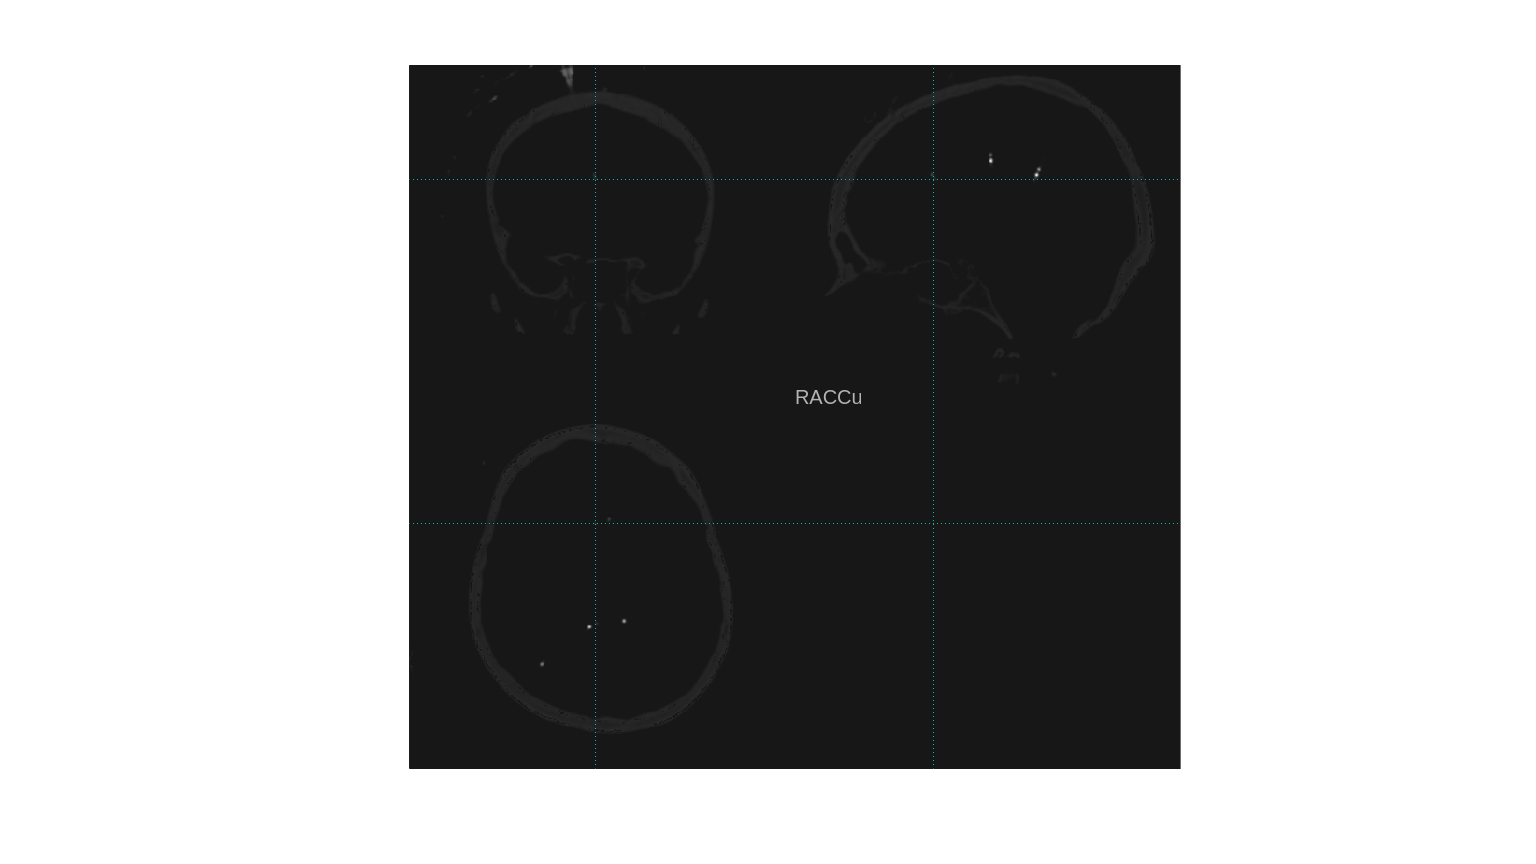

el_slice_view(pat)

## Get FreeSurfer labels in the native space

The main purpose of running FreeSurfer recon-all is to produce automated cortical parcellation. By combining electrode location with the parcellations, we can automatically assign them anatomical labels. For details of the parcellations see [https://surfer.nmr.mgh.harvard.edu/fswiki/CorticalParcellation.](https://surfer.nmr.mgh.harvard.edu/fswiki/CorticalParcellation.)

The output filenames are BIDS-compliant ([https://bids-specification.readthedocs.io/en/stable/modality-specific-files/intracranial-electroencephalography.html#channels-description-_channelstsv](https://bids-specification.readthedocs.io/en/stable/modality-specific-files/intracranial-electroencephalography.html#channels-description-_channelstsv)). Since results from this section are derived from the patient's native space (which is ACPC aligned), the identifier is `sub-xxx_space-ACPC_electrodes`.

### Input

- [Auto-loaded] MATLAB structure `elec`

- [Auto-loaded] FreeSurfer parcellation files 

### Output

- BIDS-formatted electrode location files (in .tsv and .csv)

- BrainNet Viewer node file

- BrainNet Viewer glass brain

### To do:

- Get FreeSurfer label with iElectrodes' `anatomicLabelFS` function

- Expand to also get hippocampal subfield labels

Please cite:
Xia M, Wang J, He Y (2013) BrainNet Viewer: A Network Visualization Tool for Human Brain Connectomics. PLoS ONE 8: e68910.
An example:
'The brain networks were visualized with the BrainNet Viewer (http://www.nitrc.org/projects/bnv/) (Xia et al., 2013)'.


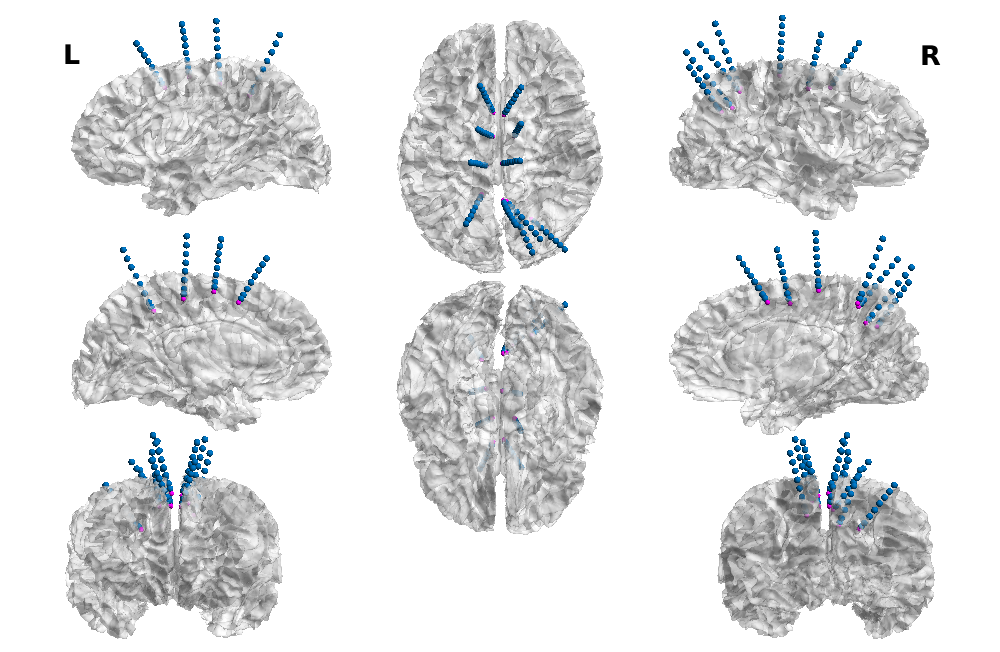

Electrode location (native ACPC space) saved:
	 CSV:           /home/qian/research/fs_subjects/TWH223/elec_loc/sub-TWH223_space-ACPC_electrodes.csv
	 TSV:           /home/qian/research/fs_subjects/TWH223/elec_loc/BIDS_outputs/ieeg/sub-TWH223_space-ACPC_electrodes.tsv
	 BrainNet node: /home/qian/research/fs_subjects/TWH223/elec_loc/sub-TWH223_space-ACPC_electrodes.node
	 Glass brain:   /home/qian/research/fs_subjects/TWH223/elec_loc/BIDS_outputs/ieeg/sub-TWH223_acq-ACPCrender_photo.jpg


el_elec_native(cfg, pat)

## Get electrode coordinates in MNI152 space

For group-level visualization of electrode location, mapping locations from native to standardized spaces is necessary. This section does a linear transform to electrode locations to map them to the MNI152 (ICBM152) space.

[https://www.bic.mni.mcgill.ca/ServicesAtlases/ICBM152Lin](https://www.bic.mni.mcgill.ca/ServicesAtlases/ICBM152Lin)

### Input

- [Auto-loaded] MATLAB structure `elec`

- [Auto-loaded] T1 scan to be registered to MNI152Lin template

### Output

- BIDS-formatted electrode location files (in .tsv and .csv)

- BrainNet Viewer node file

- BrainNet Viewer glass brain

### To do:

- Get Harvard-Oxford atlas labels with iElectrodes' `anatomicLabel` function

- Get other labels for the MNI space (e.g. AAL)

Please cite:
Xia M, Wang J, He Y (2013) BrainNet Viewer: A Network Visualization Tool for Human Brain Connectomics. PLoS ONE 8: e68910.
An example:
'The brain networks were visualized with the BrainNet Viewer (http://www.nitrc.org/projects/bnv/) (Xia et al., 2013)'.


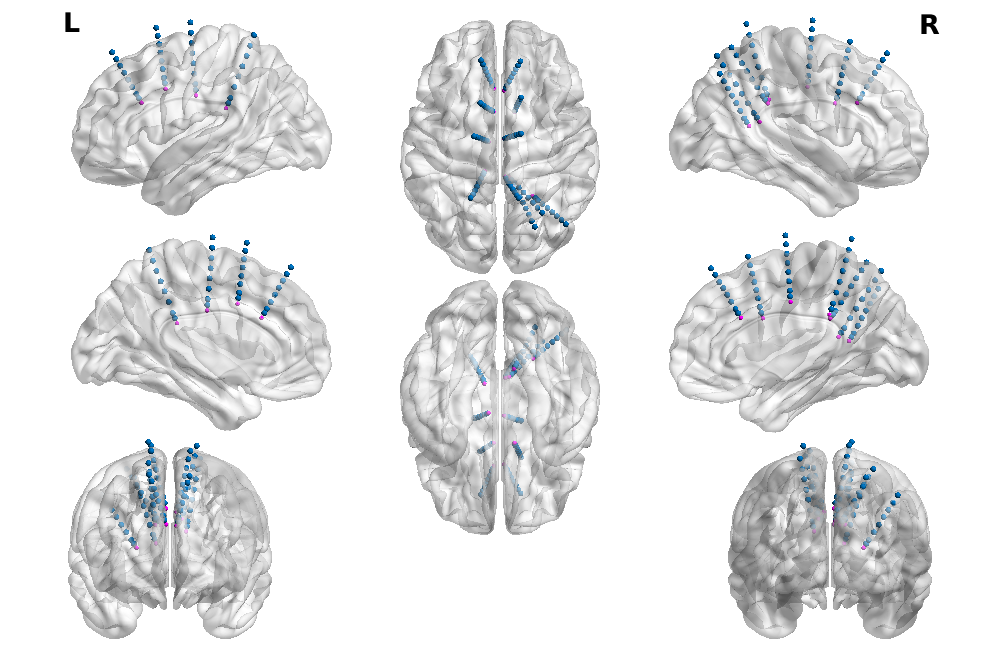

Electrode location (MNI152 space) saved:
	 CSV:           /home/qian/research/fs_subjects/TWH223/elec_loc/sub-TWH223_space-MNI152_electrodes.csv
	 TSV:           /home/qian/research/fs_subjects/TWH223/elec_loc/BIDS_outputs/ieeg/sub-TWH223_space-MNI152_electrodes.tsv
	 BrainNet node: /home/qian/research/fs_subjects/TWH223/elec_loc/sub-TWH223_space-MNI152_electrodes.node
	 Glass brain:   /home/qian/research/fs_subjects/TWH223/elec_loc/BIDS_outputs/ieeg/sub-TWH223_acq-MNI152render_photo.jpg


el_elec_mni152(cfg, pat)